# MATLAB calling TensorFlow model for Image Classification using a Live Task

Using the MATLAB Live Editor task for Python enables users to write or copy & paste Python code into MATLAB.

Steps to use the MATLAB Live Editor task for Python are:

- Write or copy & paste Python code into the Live Editor task

- Define MATLAB input variables to be called in Python

- Define Python output variables to be called in MATLAB

## Requirements

The example requires the following to be intalled:

- [MATLAB R2021b](https://www.mathworks.com/products/matlab.html) or later

- [MATLAB Live Editor task for Python](https://github.com/mathworks/MATLAB-Live-Task-for-Python) 

- [Tensorflow 2.8](https://www.tensorflow.org/install)

- [Python 3.8+](https://www.python.org/downloads/)

## Read in image

imgOriginal = imread("./Images/banana.png");
imshow(imgOriginal)

Each pretrained model in tensorflow.keras.applications takes input images of different sizes. Therefore the image being classified needs to be resized. 

imageHWSize = 480;
img = imresize(imgOriginal, [imageHWSize, imageHWSize]);

TensorFlow orients image data in a different format to MATLAB. This requires conversion (HWCN TO NHWC)

imgforTF = permute(img, [4 1 2 3]); 
batch_size = int32(1); % Tensorflow require inputs to be converted to int32.

## Classify Image via TensorFlow Coexecution

Importing EfficientNetV2L pretrained model from keras.applications

The MATLAB Live Task for Python holds the state of the Python environment between live tasks' runs whenever the code to run comes in the form of Python statements. That is, it behaves in a stateful way. 

On the contrary, if you are running a Python script file, it runs stateless.

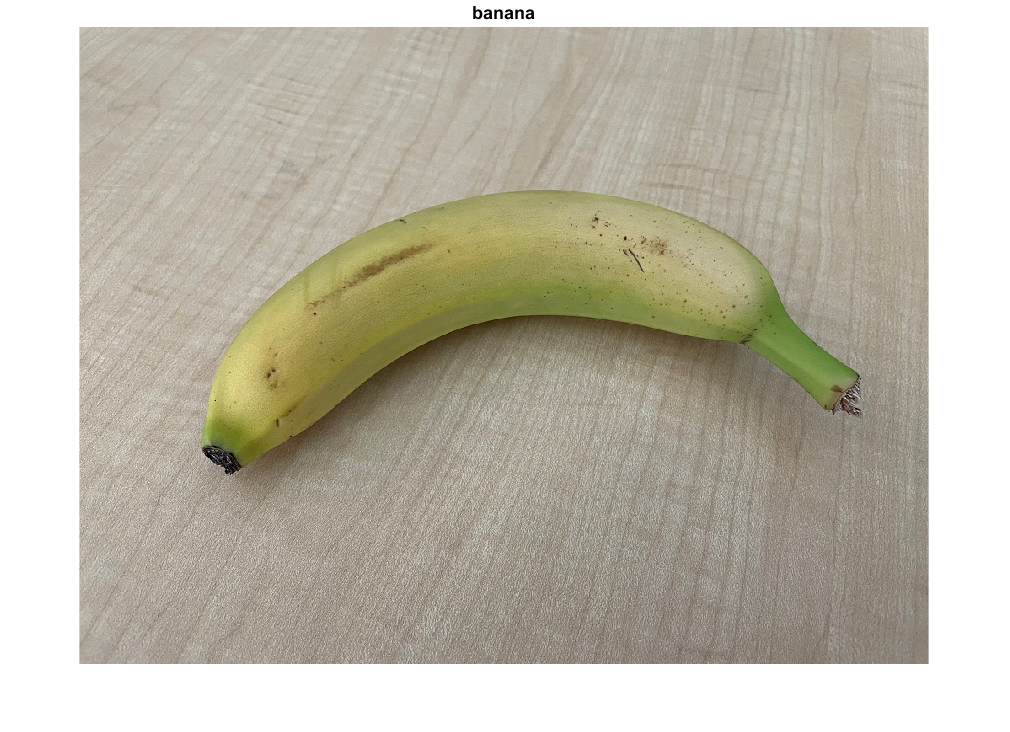

% Running Python statements from Live Task
pythonCode4 = [
    "from tensorflow.keras.applications import efficientnet_v2"
    "import numpy as np"
    "model = efficientnet_v2.EfficientNetV2L()"
    "X = np.asarray(imgforTF)"
    "X = efficientnet_v2.preprocess_input(X)"
    "Y = model.predict(X, batch_size)"
    "Y_decoded = efficientnet_v2.decode_predictions(Y)"
    "label = Y_decoded[0][0][1]; score = Y_decoded[0][0][2]"

    ];
[model, Y, label, score] = pyrun(pythonCode4, ["model", "Y", "label", "score"], "imgforTF", imgforTF, "batch_size", batch_size);
figure
imshow(imgOriginal);
title(string(label));

*© 2022, The MathWorks, Inc.*